# **DC Motor simulation**

## **Modeling - Simulink**

## 
$$\frac{\overset{\cdot }{\Theta_m } \left(s\right)}{V_a \left(s\right)}=\frac{K_t }{\left(L_a +R_a \right)\left(J_s +b\right)+K_e K_t }$$


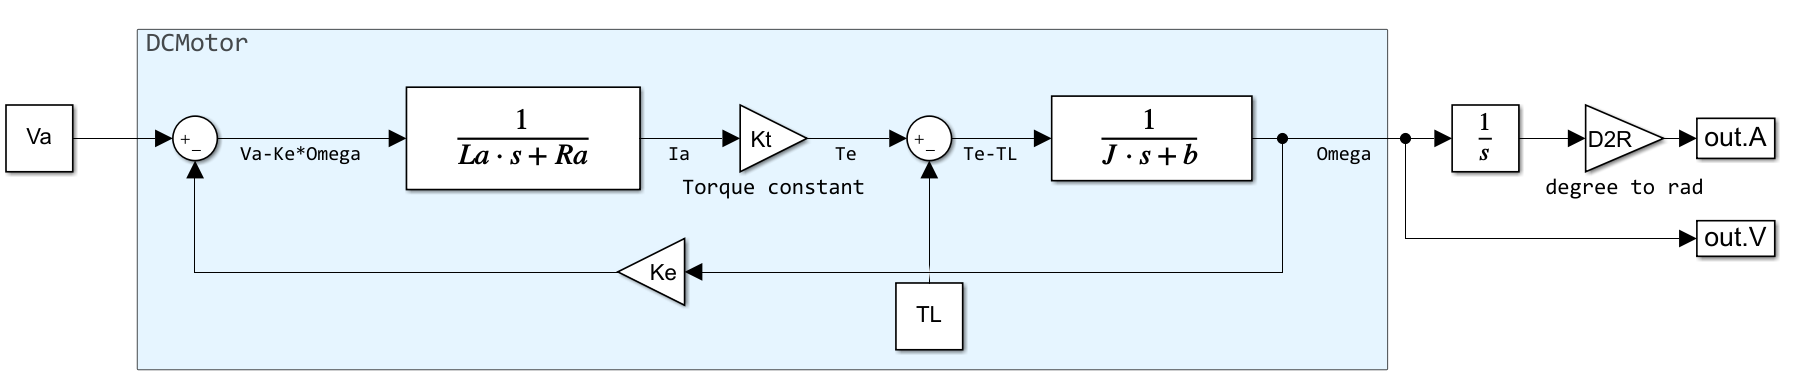

clc; clear;

## Parameter(**Maxon DCX35L Motor)**

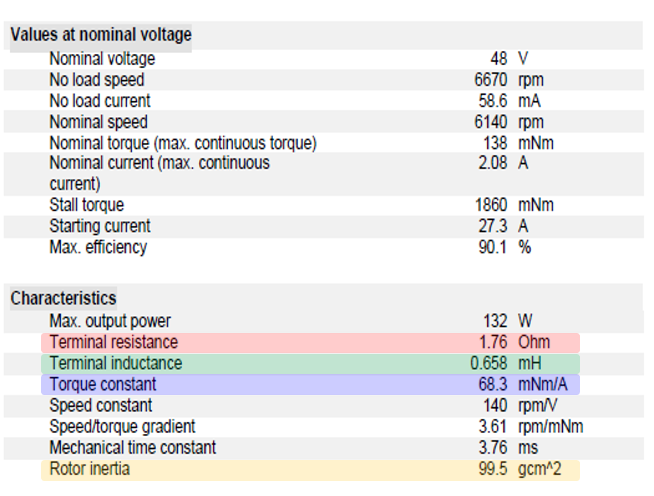

Va = 5;  % Input Voltage [V]
Ra = 1.76;                  % Resistance [Ohm]
La = 0.658e-3;              % Inductance [H]
Kt = 68.3e-3;               % Torque Constant [Nm/A]
Ke = Kt;                    % EMF Constnat(Counter Electromotive Force) [Nm/A]
 J = 99.5e-7;               % Rotor inertia [kg^2]
 t = 3.76e-3;               % Mechanical Time Constant [s]
 b = J/t;                   % Friction coefficient [Nm/(rad/s)] 
TL = 0;  % Load Torque [Nm]
D2R = 180/pi;

## **Graph(V, TL & Angel, Angular Velocity)**

simout = sim('hw1');
figure('Units', 'pixels', 'pos', [100 100 1200 400]);

### Angle 

subplot(1,2,1);
plot(simout.A.time, simout.A.signals.values, 'b', "LineWidth", 2)

xlabel('t [sec]', "FontSize", 15);
ylabel('degree', "FontSize", 15);
legend('Angle');    
title('Angule (V = ? [V])', "FontSize", 20);
grid on;
hold on;


### **Angular Velocity **

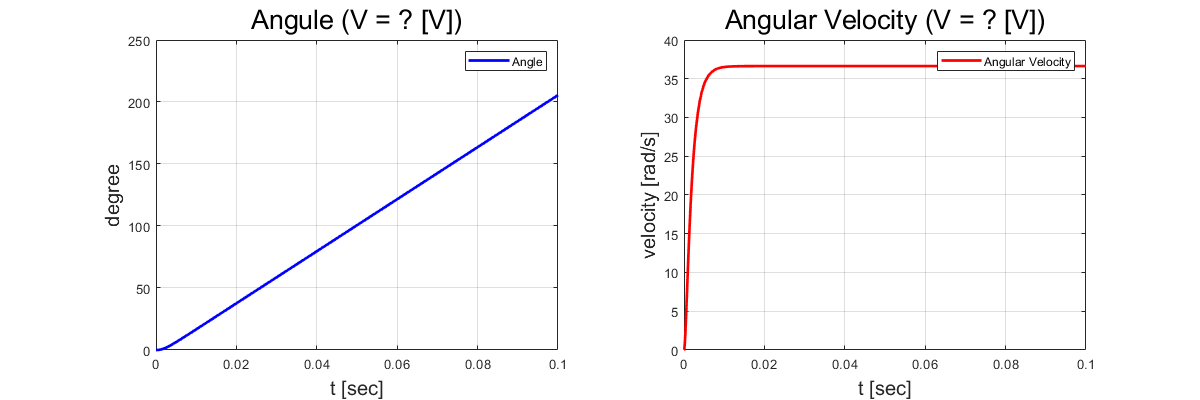

subplot(1,2,2);
plot(simout.V.time, simout.V.signals.values, 'r', "LineWidth", 2)

xlabel('t [sec]', "FontSize", 15);
ylabel('velocity [rad/s]', "FontSize", 15);
legend('Angular Velocity');
title('Angular Velocity (V = ? [V])', "FontSize", 20);
grid on;
hold on;